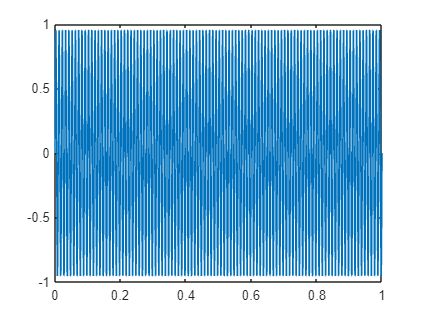

% Given parameters
message_frequency = 10; % Hz
carrier_frequency = 100; % Hz
sampling_frequency = 1000; % Hz

% Define time vector
t = 0:1/sampling_frequency:1;

% Generate message signal as sin(2*pi*fm*t)
message_signal = sin(2*pi*message_frequency*t);

% Generate carrier signal as sin(2*pi*fc*t)
carrier_signal = sin(2*pi*carrier_frequency*t);
plot(t, carrier_signal);

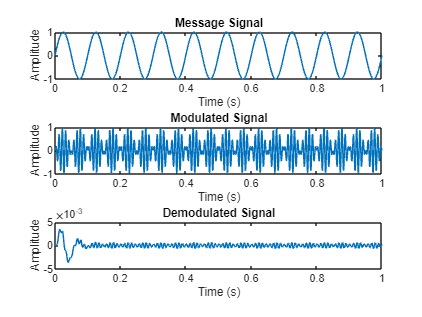

% Perform QAM modulation by multiplying message signal with carrier signal
modulated_signal = message_signal .* carrier_signal;

% Design a low pass Butterworth filter for demodulation
cutoff_frequency = 20; % Hz
filter_order = 5; % Filter order
[b, a] = butter(filter_order, cutoff_frequency/(sampling_frequency/2), 'low');

% Apply the filter to the modulated signal
filtered_signal = filter(b, a, modulated_signal);

% Apply gain to the filtered signal for demodulation
gain = 2;
demodulated_signal = filtered_signal * gain;

% Plot the signals
figure;
subplot(3, 1, 1);
plot(t, message_signal);
title('Message Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(3, 1, 2);
plot(t, modulated_signal);
title('Modulated Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(3, 1, 3);
plot(t, demodulated_signal);
title('Demodulated Signal');
xlabel('Time (s)');
ylabel('Amplitude');